# **第十四章 自编码器**

**版权申明：**

- **本文件由山西大学复杂系统研究所郁磊副教授开发完成。未取得授权的情况下，请勿私自传播，传播形式包括但不限于：拷贝、传输、打印等。授权相关事宜请通过电子邮件沟通联系（Email: yulei@sxu.edu.cn）。**

- **本文件在开发过程中得到了迈斯沃克软件（北京）有限公司与教育部产学合作协同育人项目的支持。**

## 14.1 自编码器简介

        在前面的章节中，我们讲到过在有监督学习范式下，特征提取的方式主要包括：

- **基于人工先验知识的特征提取。**在各个应用领域的发展过程中，人们都逐步总结出了一些特征提取方法（譬如：在人脸识别领域中，从早期的提取五官特征，到后来的提取人脸轮廓骨架特征）。这些提取出来的特征都具有明确的物理意义，都代表了人们从不同角度的理解与知识。

- **基于空间映射的特征提取。**在全连接神经网络中，输入层的原始数据经过前向传播到达隐含层后，隐含层神经元的输出可以看作是原始数据经过一个空间映射后得到的。类似的，在支持向量机中，当在低维特征空间线性不可分时，可以利用核函数将低维特征映射到高维空间。

- **基于预训练模型的特征提取。**在卷积神经网络中，可以将待提取特征的图像输入到AlexNet、GoogLeNet、Vgg16/19、ResNet等预训练模型，当前向传播到某个指定的层时，提取出对应的特征图(Feature Map)。

        不论采用哪种特征提取方法，我们都需要进一步验证提取出的特征是否足够“好”？为了回答这个问题，其实很简单，因为对于有监督学习范式而言，只需要将从样本中提取出的特征与样本对应的标签构建成样本对(X, Y)，训练模型并计算相应的评价指标(如：RMSE、Accuracy等)，就可以量化评价提取出的特征的优劣了。

        然而，对于无监督学习范式而言，因为缺少样本的标签信息，上述方法就无法适用了。那么，应该怎样验证提取出的特征是否足够“好”？换言之，应该采用怎样的方法进行特征提取，才能够保证提取出的特征尽可能保留原始数据中的信息呢？在第七章中，主成分分析(PCA)是一种经典的特征提取（同时也实现了特征降维压缩）方法，其通过“方差”信息尽可能不丢失的方式给出了一个行之有效的解决方案。

        与主成分分析方法不同，自编码器(Auto-Encoder)给出了一个充分展现朴素思想的解决思路：若能够从提取出的特征中完整地重构（还原）出原始数据，那么就可以说提取出的特征是“好”的特征。自编码器的拓扑结构如图1所示，由编码器(Encoder)和解码器(Decoder)两部分级联而成。在对编码器和解码器进行拓扑结构设计时，可以采用全连接神经网络的结构，也可以采用卷积神经网络的结构。编码器的作用是对原始数据X进行特征提取，得到特征Z（一般情况下，Z的维度远小于X的维度，因此编码器同时起到了降维的作用），解码器的作用是尝试从Z中重构（还原）出原始数据，即尽可能使解码器的输出$\overset{\wedge }{X}$逼近原始数据X。

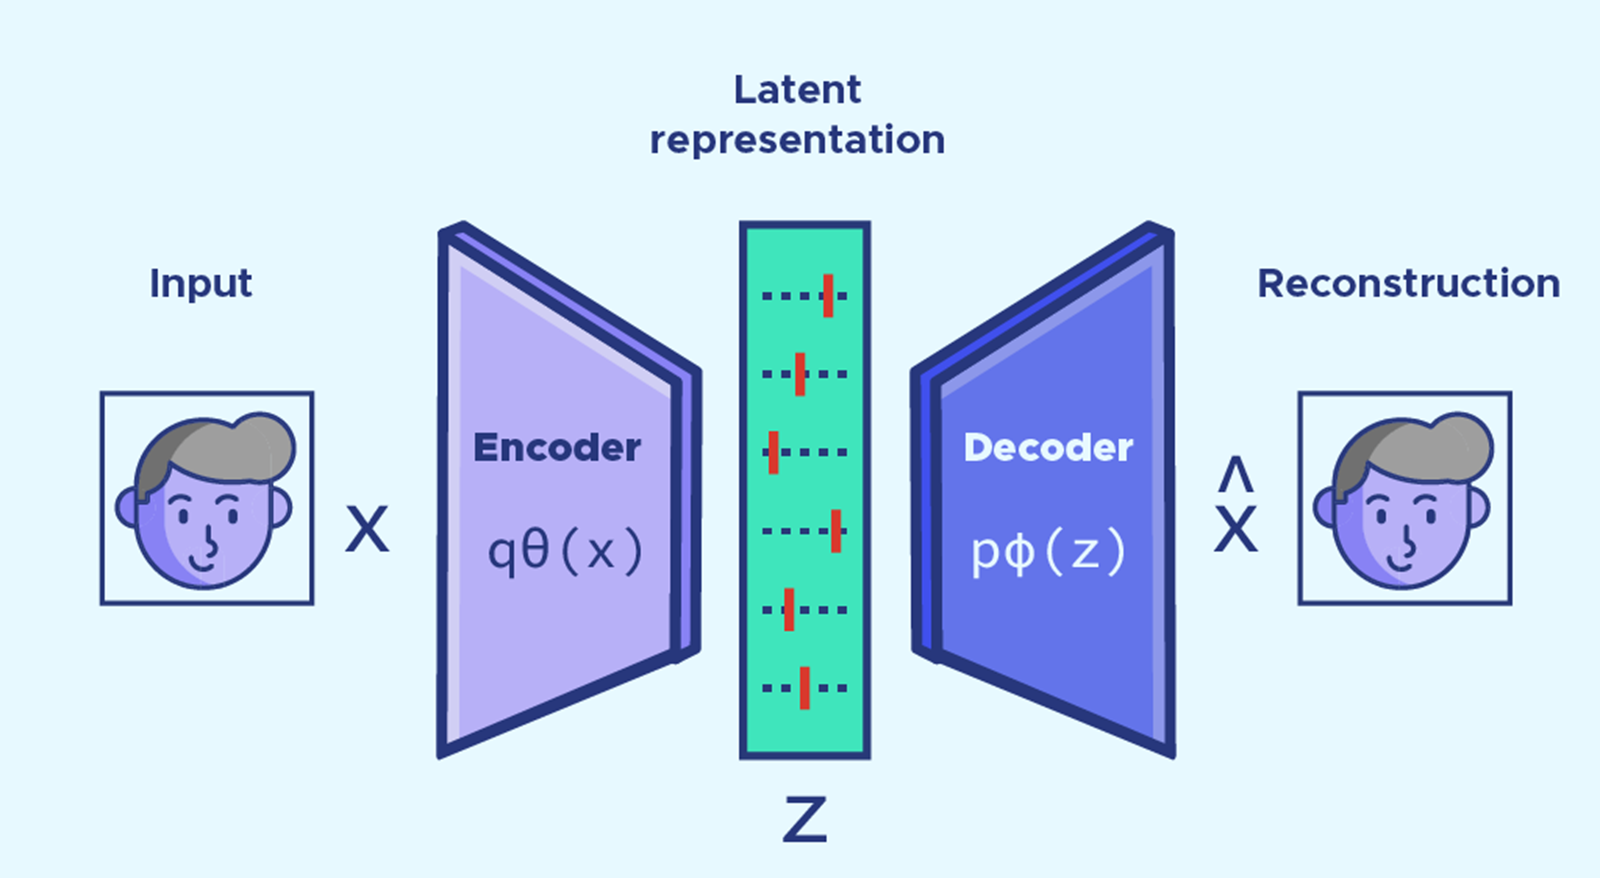

图1 自编码器的拓扑结构

        自编码器的训练过程如图2所示。细心的读者不难发现，尽管自编码器属于无监督学习范式，但其训练过程是一种特殊的有监督学习范式。理由如下：一般情况下，对于有监督学习范式来说，训练的过程是使得模型的输出（预测值）$\overset{\wedge }{y}$与真实值y之间的误差越来越小，而自编码器的训练过程是使得模型的输出$\overset{\wedge }{X}$与输入X之间的误差越来越小。因此，自编码器相当于是构建了一种特殊形式的样本对（X, X），使其从无监督学习范式变成了有监督学习范式，再沿用有监督学习范式的方式进行训练。**需要注意的是，当自编码器模型训练完成后，我们感兴趣的不是解码器的输出**$\overset{\wedge }{X}$**，而是编码器的输出C。**

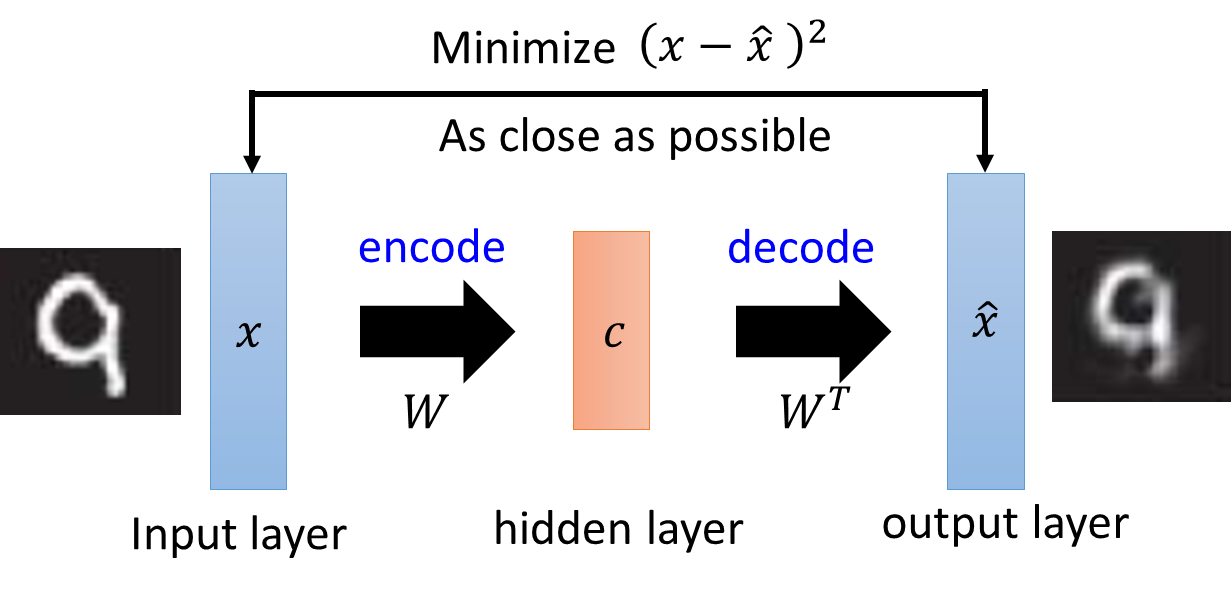

图2 自编码器的训练过程

## 14.2 自编码器的若干变体

- ** 降噪自编码器（Denoising Auto-Encoder）**

        如图3所示，当编码器的输入$x^{\prime }$中含有噪声时，若采用如图2所示的方式进行训练时，从解码器的输出端重构出的$\overset{\wedge }{X}$中必然也会包含噪声信息，即意味着从原始信号$x^{\prime }$经编码器特征提取后得到的c同时保留了有效信息和噪声信息。这并不是我们期望得到的结果，我们期望从解码器的输出端重构出的$\overset{\wedge }{X}$中仅包含有效信息部分x，同时剔除噪声信息。为了实现这个目的，降噪自编码器的训练任务是使得重构信号$\overset{\wedge }{X}$与有效信息x之间的偏差越来越小。这样，最终从编码器的输出端提取出的特征c，对于编码器的输入$x^{\prime }$而言，同时起到了降噪、特征提取和降维的三重目的。

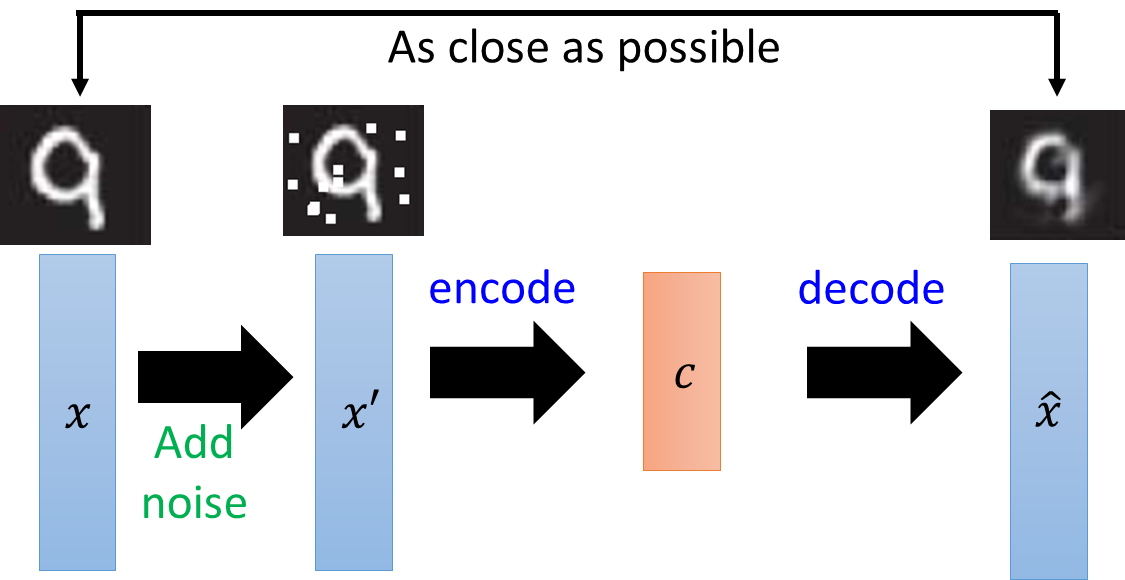

图3 降噪自编码器拓扑结构

- **变分自编码器（Variational Auto-Encoder）**

        变分自编码器是一种生成模型，它通过将输入数据映射到一个潜在空间来学习数据的分布。与传统的自编码器不同，VAE在编码过程中引入了随机性，使得每个输入点被映射到潜在空间中的一个分布上，而不是一个固定的点。

        变分自编码器的拓扑结构如图4所示，编码器负责将输入数据映射到潜在空间的分布（通常是高斯分布），接受输入数据并输出两个参数（均值和方差），这些参数定义了潜在空间中的高斯分布。而解码器则从高斯分布中采样一个点，并试图重建原始输入。

       ** VAE的训练包括两个主要部分：最小化重建误差和正则化潜在空间。**

- ** 最小化重建误差：**确保解码器能够从潜在空间的采样点重建出与原始输入尽可能相似的数据。 

- **正则化潜在空间：**通过KL散度（Kullback-Leibler divergence）惩罚来确保编码的潜在空间分布接近先验分布（通常是标准正态分布）。

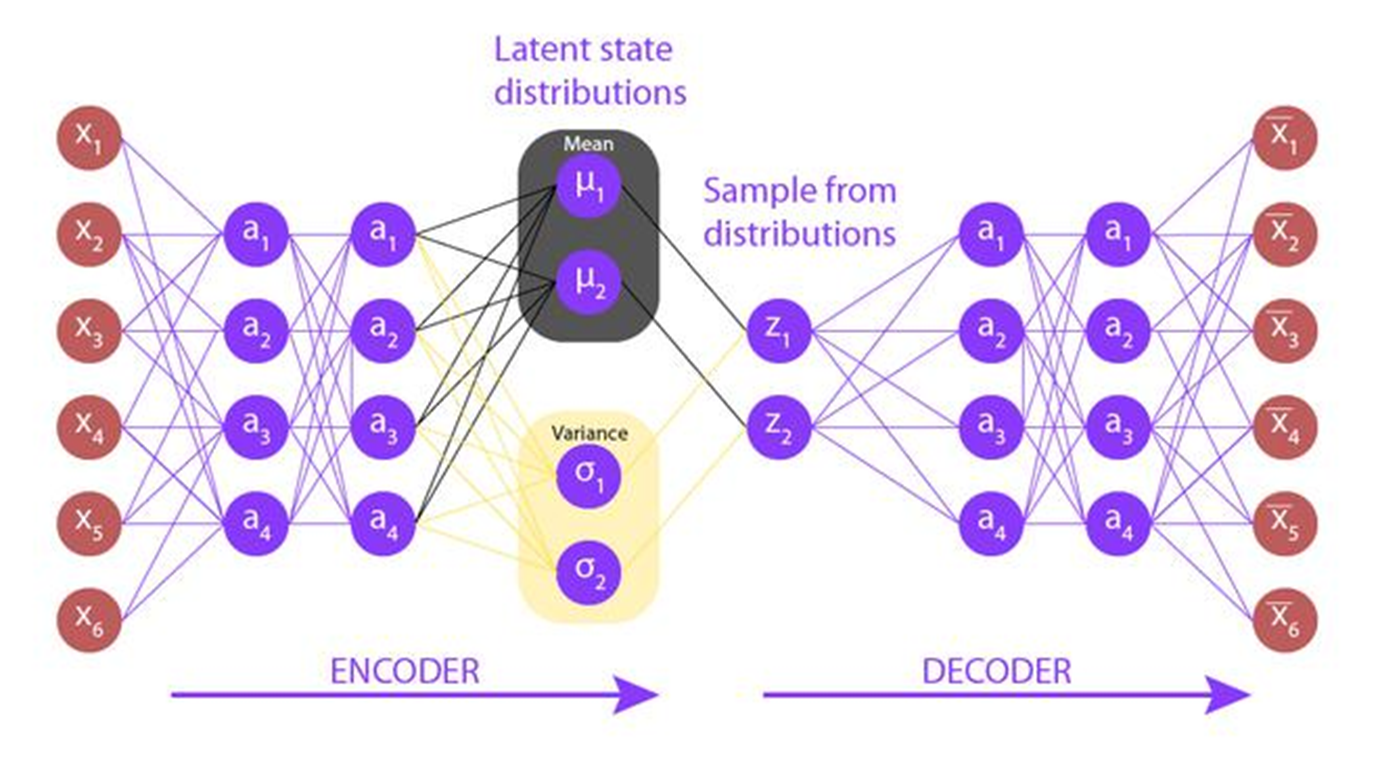

图4 变分自编码器的拓扑结构

       ** 补充知识：除变分自编码器外，生成模型还包括：生成式对抗网络（GAN）、扩散模型（Diffusion Model）等。**

- **掩码自编码器（Masked Auto-Encoder）**

        日常生活中，我们家中的一些老照片因为年代久远经常会出现一些破损，传统的修复方法大多基于图像中相邻像素点之间通常较为相关（边缘区域除外）这一理论。当图像中破损的部分较小时，利用周围的像素点信息可以较好地重构出破损部分内容。然而，当图像中破损的部分较大（譬如：≥80%）时，利用传统的修复方法通常难以准确地还原破损部分的内容。

        为了解决该问题，何恺明团队于2022年提出了掩码自编码器模型，其拓扑结构如图5所示。该架构包括一个编码器和一个轻量级解码器。编码器仅对可见的图像补丁子集（不包括掩码标记）进行操作，而解码器则重建原始图像。在预训练阶段，随机选择一大部分（例如75%）图像补丁被掩码遮盖。编码器应用于剩余的可见补丁，编码后的补丁和掩码标记一起被送入解码器。解码器的输出是代表补丁的像素值向量。使用均方误差（MSE）计算重建图像与原始图像之间的差异，损失仅在被掩码的补丁上计算。

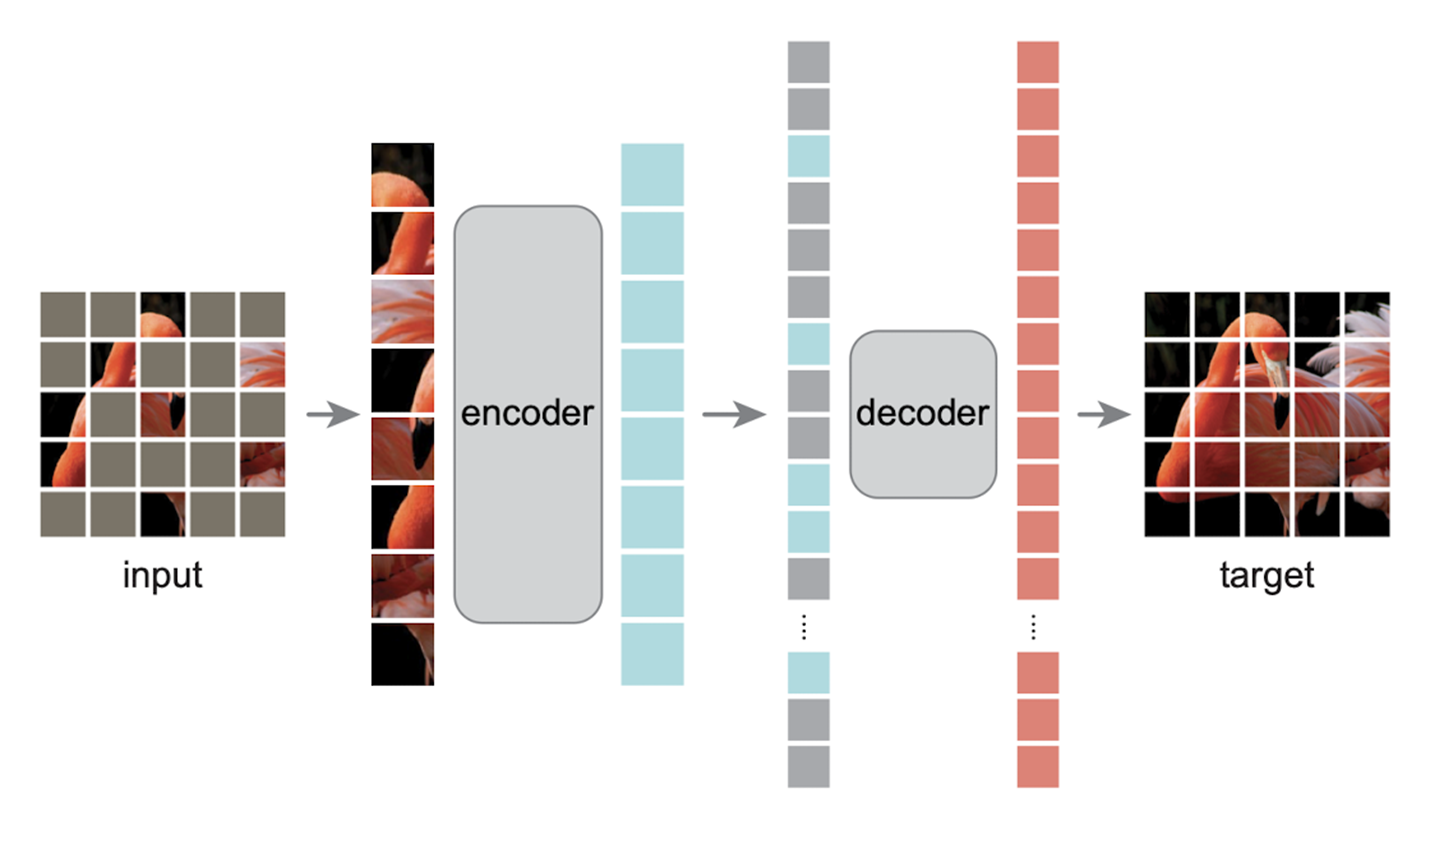

图5 掩码自编码器的拓扑结构

## 14.3 案例：基于自编码器的变量降维

- **导入数据集**

load spectra_data.mat

- **训练集/测试集划分**

        不失一般性，这里采用随机法产生训练集和测试集，即随机产生k个样品作为训练集，剩余的60-k个样品作为测试集。

  % 随机产生训练集和测试集
  temp = randperm(size(NIR,1));
  k = 50;
  
  % 训练集：k个样本
  P_train = NIR(temp(1:k),:)';
  T_train = octane(temp(1:k),:)';
  
  % 测试集：60-k个样本
  P_test = NIR(temp(k+1:end),:)';
  T_test = octane(temp(k+1:end),:)';

- **数据归一化**

  % 训练集X归一化
  [p_train, ps_input] = mapminmax(P_train,0,1);
  
  % 利用训练集X归一化的标准对测试集X进行归一化
  p_test = mapminmax('apply',P_test,ps_input);
  
  % 训练集Y归一化
  [t_train, ps_output] = mapminmax(T_train,0,1);

- **创建自编码器，对P_train进行训练**

autoenc1 = trainAutoencoder(p_train, 20, ...
                            'MaxEpochs',1000, ...
                            'L2WeightRegularization',0.004, ...
                            'SparsityRegularization',4, ...
                            'SparsityProportion',0.15, ...
                            'ScaleData', false);

- **提取编码器的输出特征**

feat1 = encode(autoenc1, p_train);

- **利用提取的特征，与T_train构建BP神经网络模型**

hiddenNeurous = 5;   % 隐含层神经元个数
net = feedforwardnet(hiddenNeurous);

% 设置训练参数
net.trainParam.epochs = 1000;    % 最大迭代次数
net.trainParam.goal = 0.005;      % 训练目标
net.trainParam.lr = 0.01;        % 学习率
  
% BP神经网络训练
net = train(net, feat1, t_train);

- **创建自编码器，对P_test进行训练**

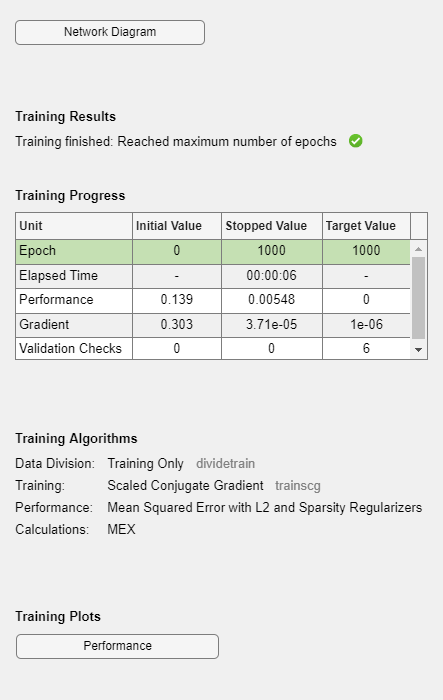

autoenc2 = trainAutoencoder(p_test, 20, ...
                            'MaxEpochs',1000, ...
                            'L2WeightRegularization',0.004, ...
                            'SparsityRegularization',4, ...
                            'SparsityProportion',0.15, ...
                            'ScaleData', false);

- **提取编码器的输出特征**

feat2 = encode(autoenc2, p_test);

- **BP神经网络模型预测**

% BP神经网络预测
t_sim = sim(net, feat2);

% 反归一化处理
T_sim = mapminmax('reverse', t_sim, ps_output);

- **性能评价**

  % 绝对误差
  absolute_error = T_sim - T_test

absolute_error =    -1.5897    2.1995   -2.6872    6.0877   -3.3314    6.6541   -1.4507    2.5293   -1.9473   -2.6966



  % 相对误差error
  relative_error = abs(T_sim-T_test) ./ T_test

relative_error =     0.0180    0.0249    0.0306    0.0720    0.0377    0.0788    0.0164    0.0297    0.0223    0.0304


  % 均方根误差
  rmse = sqrt(mse(T_sim, T_test))

rmse = 3.5579


  % 决定系数R^2  
  N = size(P_test,2);
  R2 = (N * sum(T_sim .* T_test) - sum(T_sim) * sum(T_test))^2 / ((N * sum((T_sim).^2) - (sum(T_sim))^2) * (N * sum((T_test).^2) - (sum(T_test))^2))

R2 = 0.4131

- **结果绘图可视化**

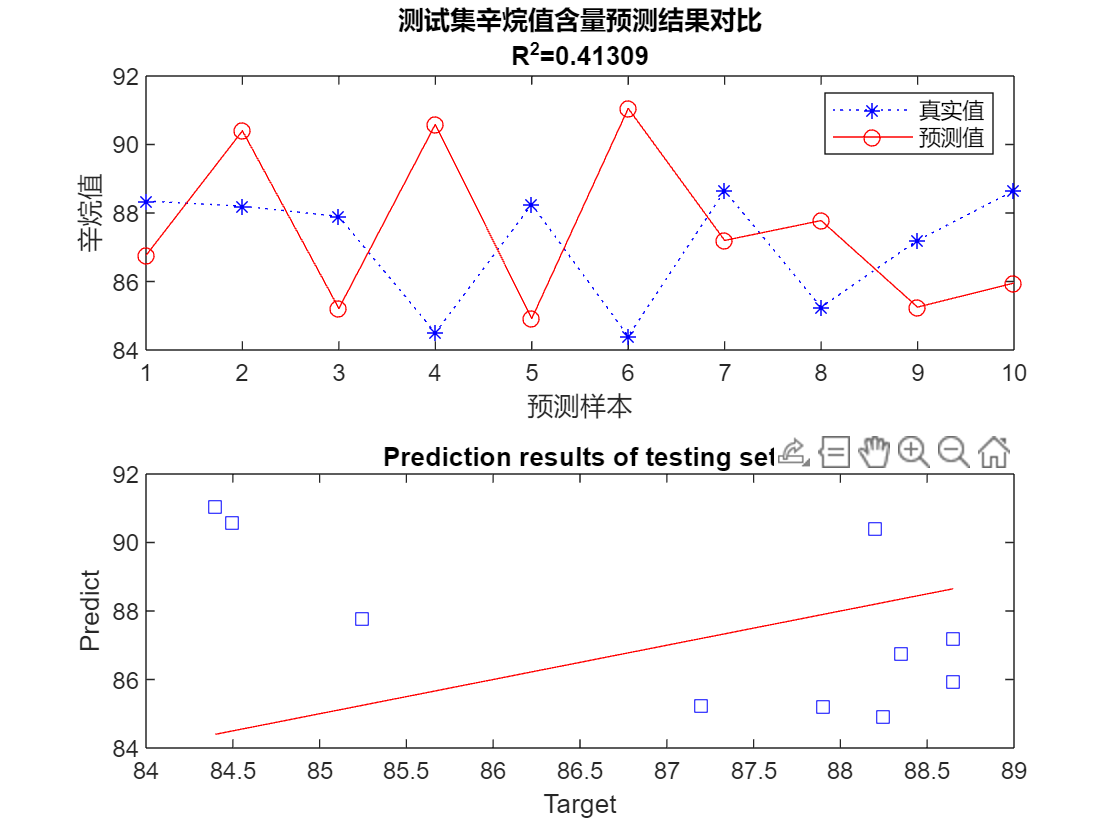

    figure
    subplot(2, 1, 1)
    plot(1:N,T_test,'b:*',1:N,T_sim,'r-o')
    legend('真实值','预测值')
    xlabel('预测样本')
    ylabel('辛烷值')
    string = {'测试集辛烷值含量预测结果对比';['R^2=' num2str(R2)]};
    title(string)

    subplot(2, 1, 2)
    plot(T_test,T_test,'r-')
    hold on
    plot(T_test,T_sim,'bs')
    
    xlabel('Target')
    ylabel('Predict')
    title('Prediction results of testing set')